# Robot Navigation Project - Organize Seque4nce Data

This dataset was obtained from the UCI Machine Learning Repository. 

You can find more information on this dataset here:

[https://archive.ics.uci.edu/ml/datasets/Wall-Following+Robot+Navigation+Data](http://Wall-Following Robot Navigation Data Set)

Load the unprocessed sensor data. This mat file contains 3 variables.

- `label`: The action the robot should take at this time step. At any point, the robot can either move forward, turn slightly to the left, turn slightly to the right, or turn sharply to the right

- `sensor1`: Sensor reading from the front of the robot

- `sensor2`: Sensor reading from the left of the robot

load robotData.mat

## Display data

Display the first feature of the sequence data. The function `displaySequence` located at the bottom of the script. This function takes two inputs, the sensor data and the class labels.

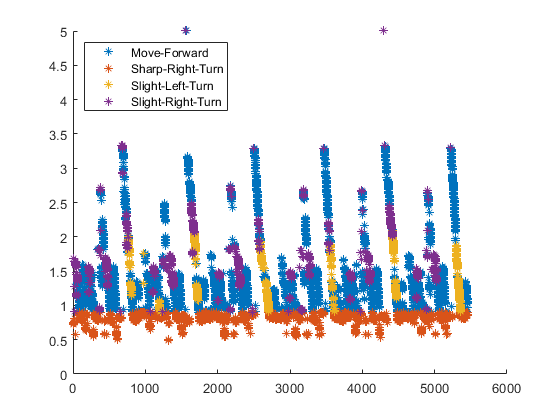

displaySequence(sensor1,label)

Display the second feature.

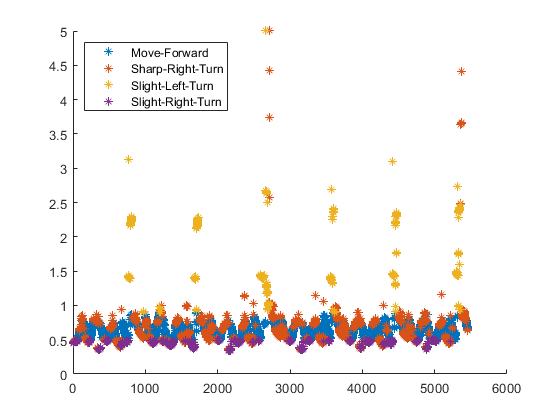

displaySequence(sensor2,label)

## Create matrix of sequence data

Concatenate the two vectors of sensor data into one matrix.

X = [sensor1 sensor2];

Transpose the matrix so that the columns are the time steps.

X = X'

X =     1.6870    1.6870    1.6870    1.6870    1.6870    1.6860    1.6840    1.6800    0.7530    0.7440    0.7350    0.7290    0.7230    0.7570    0.7600    0.7570    0.7610    0.7620    0.7650    0.8120    0.8140    0.8110    0.9080    1.2700    1.6390    1.6380    1.6370    1.6360    1.6350    1.6350    1.6350    1.6350    1.6330    1.6290    1.6240    1.6180    1.6110    1.6090    1.6030    0.5760    1.5810    1.5720    1.5620    1.5530    1.1790    1.1670    1.1590    1.1510    1.1430    1.1360
    0.4450    0.4490    0.4490    0.4490    0.4490    0.4460    0.4510    0.4530    0.4570    0.4620    0.4670    0.4690    0.4770    0.4800    0.4830    0.4820    0.4820    0.4820    0.4820    0.4810    0.4800    0.4790    0.4780    0.4770    0.4760    0.4750    0.4740    0.4750    0.4750    0.4750    0.4750    0.4750    0.4750    0.4740    0.4730    0.4730    0.4730    0.4720    0.4710    0.4710    0.4710    0.4710    0.4700    0.4700    0.4700    0.4700    0.4710    0.4710    0.4710    0

## Transpose sequence labels

Each time step of the sequence data has a label. The labels should be stored in a row vector, but currently it is a column. Take the transpose.

Y = label';

view the class distribution of the data.

summary(label)

     Move-Forward           2205 
     Sharp-Right-Turn       2097 
     Slight-Left-Turn        328 
     Slight-Right-Turn       826 


## Separate training and testing data

The last 1000 time steps of the sequence are used to test  network. 

n = 1000;
XTrain = X(:,1:end-n);
YTrain = Y(1:end-n);

XTest = X(:,end-n+1:end);
YTest = Y(end-n+1:end);

This function displays the sequence data colored by its corresponding label.

function displaySequence(X,Y)
    figure
    classNames = categories(Y);
    for j = 1:length(classNames)
        label = classNames(j);
        idx = find(Y == label);
        hold on
        plot(idx,X(idx),'*')
    end
    hold off
    legend(classNames,'Location','northwest')
end


# Robot Navigation Project - Sequence Classification